##  Load Data

% Load each trial
controls = {CT1, CT2, CT3, CT4, CT5, CT6, CT7, CT8}

controls = 1×8 cell array
    {1893260×2 single}    {3726858×2 single}    {3716176×2 single}    {3675772×2 single}    {3640352×2 single}    {3615364×2 single}    {3715866×2 single}    {3653016×2 single}


knockouts = {KO1, KO2, KO3, KO4, KO5, KO6, KO7, KO8}

knockouts = 1×8 cell array
    {1890190×2 single}    {3689071×2 single}    {3517539×2 single}    {3770358×2 single}    {3691845×2 single}    {3938323×2 single}    {3639901×2 single}    {3861380×2 single}


test = {randi([-20 20],100,2)}

test = 1×1 cell array
    {100×2 double}


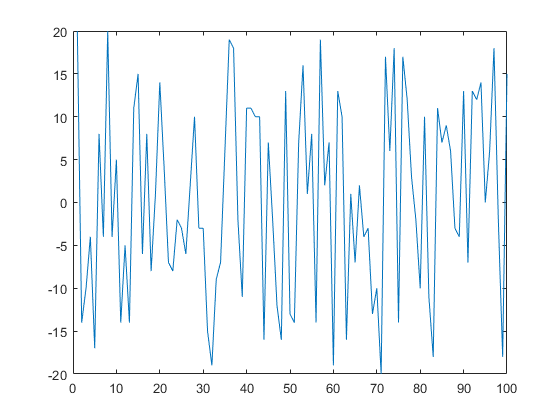

figure; plot (test{1}(:,2))


limit = 4

limit = 4

xx = artifact_filter(test, limit)

jj = 1

length after deleting entry is
    99

length after deleting entry is
    98

length after deleting entry is
    97

length after deleting entry is
    96

length after deleting entry is
    95

length after deleting entry is
    94

length after deleting entry is
    93

length after deleting entry is
    92

length after deleting entry is
    91

length after deleting entry is
    90

length after deleting entry is
    89

length after deleting entry is
    88

length after deleting entry is
    87

length after deleting entry is
    86

length after deleting entry is
    85

length after deleting entry is
    84

length after deleting entry is
    83

length after deleting entry is
    82

length after deleting entry is
    81

length after deleting entry is
    80

length after deleting entry is
    79

length after deleting entry is
    78

length after deleting entry is
    77

length after deleting entry is
    76

length after deleting entry is
    75

length after deleting ent

result = 1×1 cell array
    {24×2 double}


xx = 1×1 cell array
    {24×2 double}



disp(xx)

    [24×2 double]



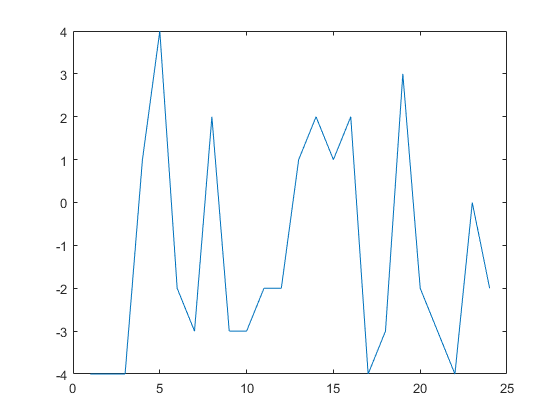

figure; plot (xx{1}(:,2))

test = {KO1(1:1000000,:), KO2(1:1000000,:)}

test = 1×2 cell array
    {1000000×2 single}    {1000000×2 single}


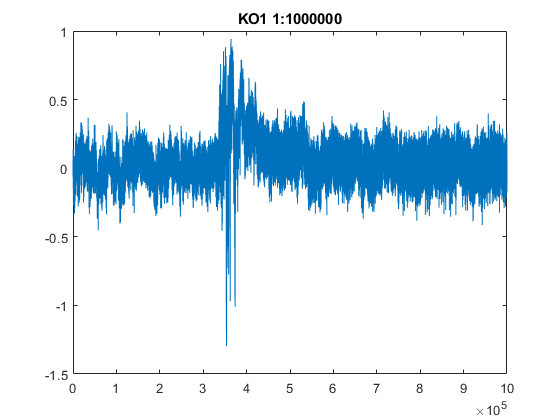


figure; plot(KO1(1:1000000,2)); title ('KO1 1:1000000')

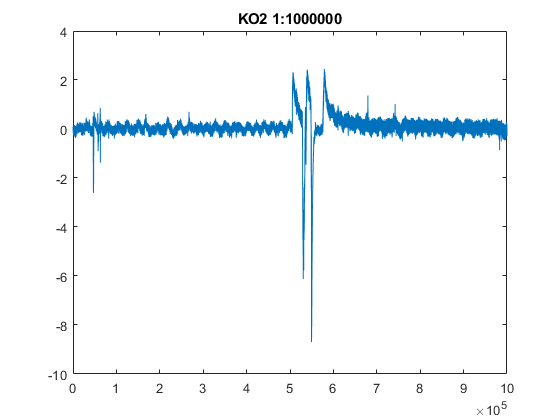

figure; plot(KO2(1:1000000,2)); title ('KO2 1:1000000')


limit = 0.4

limit = 0.4000

controls_filter04 = artifact_filter(test, limit)

cell_array = 1×2 cell array
    {970693×2 single}    {1000000×2 single}


cell_array = 1×2 cell array
    {970693×2 single}    {903429×2 single}


result = 1×2 cell array
    {970693×2 single}    {903429×2 single}


controls_filter04 = 1×2 cell array
    {970693×2 single}    {903429×2 single}


xx = controls_filter04

xx = 1×2 cell array
    {970693×2 single}    {903429×2 single}


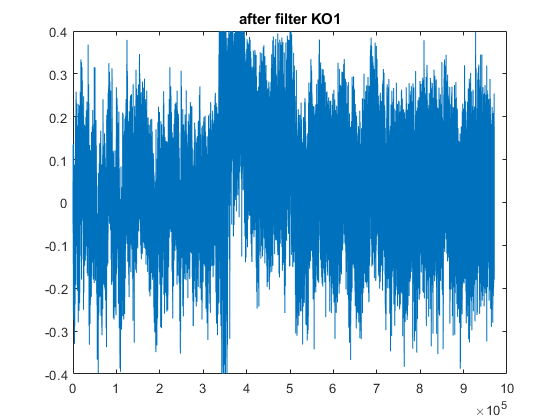


figure; plot(xx{1}(:,2)); title('after filter KO1')

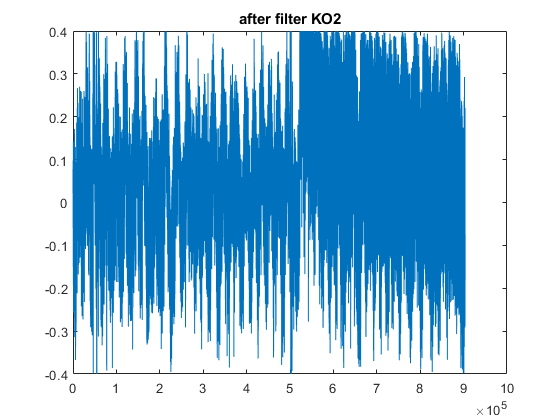

figure; plot(xx{2}(:,2)); title('after filter KO2')

## Set Parameters for Chronux Spectrogram

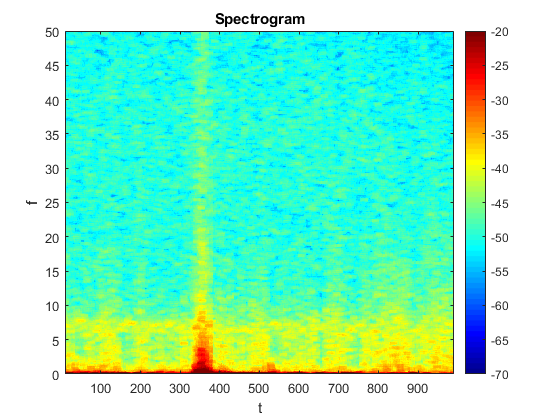

% Setting parameters
params.Fs = 1000; %Sampling frequency of input data (1000 = 1000 hz = 1 sample per millisecond)
params.fpass = [0 50]; % Which frequencies to look at [lowest_wanted highest_wanted]
params.pad = 0; % will add 0's to fit into a power of 2 for better calculation (0 is default and adds 0's to the next power of 2)
TW = 5; % the time-bandwidth product 
K = 9; % the number of tapers, K = 2*TW - 1 
params.tapers = [TW K]; 


plot_spectrogram(KO1(1:1000000,:), [20 1], params)

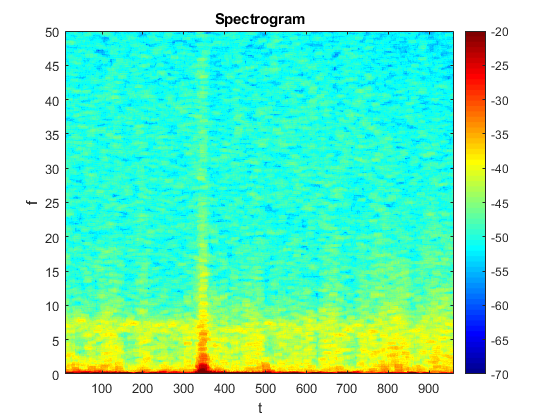

plot_spectrogram(xx{1}, [20 1], params)

## Filter out Artifacts 

function result = artifact_filter(cell_array, limit)
for ii = 1:length(cell_array)
    
    
    cell_array{ii}(abs(cell_array{ii}(:,2)) >= limit, :) = []
       
    
end
result = cell_array
end

## Calculate and Plot Spectrogram

function result = plot_spectrogram (arrayx, movingwin, params)

[S2, t2, f2] = mtspecgramc(arrayx(:,2), movingwin,params);
figure; plot_matrix(S2,t2,f2); colorbar; colormap jet; caxis ([-70 -20])

end